**Skills 8: Kinetics and dissolved oxygen dynamics in aquatic systems**

**1.)**

**Given: **

- Initial concentration = $50\;\mathrm{mg}/L$

- 
$$k_0 =0\ldotp 5\;\mathrm{mg}\;l^{-1} \;{\mathrm{day}}^{-1}$$


- 
$$k_1 =0\ldotp 01\;{\mathrm{day}}^{-1}$$


- 
$$k_2 =0\ldotp 0002\;{\mathrm{day}}^{-1} \;{\mathrm{mg}}^{-1} \;l$$


C = 50;
T = [0, 25, 50, 75, 100];
k0 = 0.5;
k1 = 0.01;
k2 = 0.0002;

**Required:**

1.1) Plot concentration vs time over 100 days if removal is by zero order, first order, and second order kinetics.

1.2) Calculate and plot cumulative removal (0 to 100% vs time).

**Sketch:**

**Theory:**

This problem will use the following equations:

- Zero-order: $\frac{\mathrm{dC}}{\mathrm{dt}}=-k_0$

- First-order: $\frac{\mathrm{dC}}{\mathrm{dt}}=-k_1 *A$

- Second-order: $\frac{\mathrm{dC}}{\mathrm{dt}}=-k_2 *A^2$

- Percent removal: $\left(\frac{C_0 -C}{C_0 }\right)*100$

**Assumptions:**

- No additional inputs of material over time.

**Solution:**

1.1)

- Zero-order kinetics:

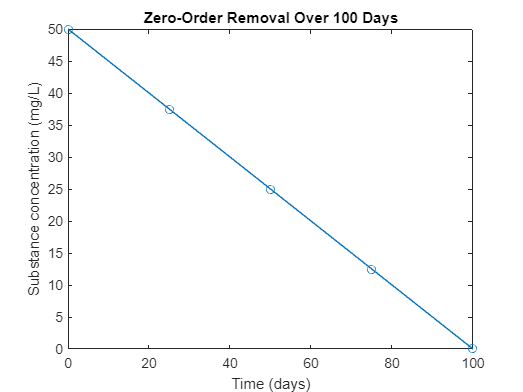

C0 = C-(k0*T);

figure
plot(T,C0,'o-')
title(["Zero-Order Removal Over 100 Days"])
ylabel("Substance concentration (mg/L)")
xlabel("Time (days)")

- First-order kinetics:

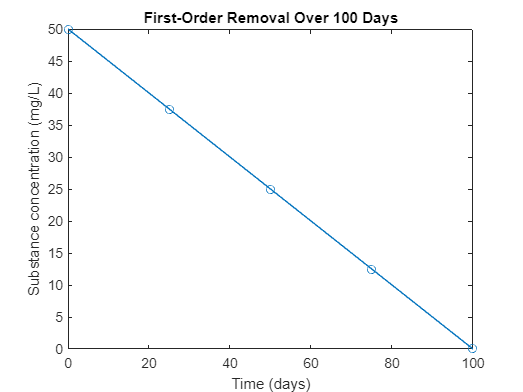

C1 = C-(k1*C*T);

figure
plot(T,C1,'o-')
title(["First-Order Removal Over 100 Days"])
ylabel("Substance concentration (mg/L)")
xlabel("Time (days)")

- Second-order kinetics:

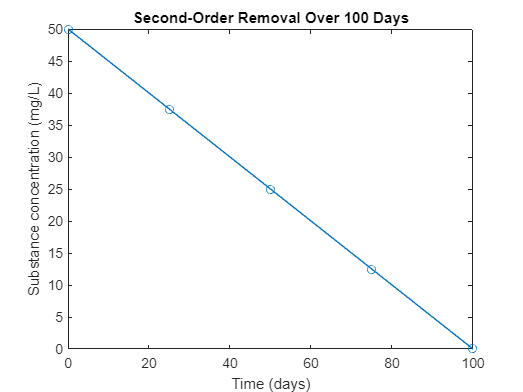

C2 = C+(-k2*(C^2)*T);

figure
plot(T,C2,'o-')
title(["Second-Order Removal Over 100 Days"])
ylabel("Substance concentration (mg/L)")
xlabel("Time (days)")

- Percent removal over time:

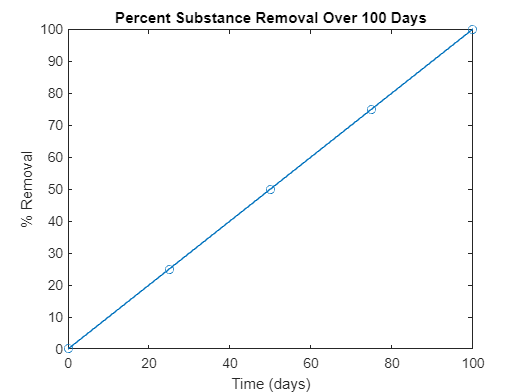

Pct = ((C-C0)/C)*100;

figure
plot(T,Pct,'o-')
title(["Percent Substance Removal Over 100 Days"])
ylabel("% Removal")
xlabel("Time (days)")

**Discussion:**

- In this case, removal of the substance using zero, first, and second order kinetics was identical. This shows the influence of the rate constant (k), which was quite different for each of the three questions. If the k values had been slightly different, then the substance removal rates would change as well.

**15.)**

**Given:**

- Elevation change = 2600 m - 700 m = 1900 m

- Average temperature = $13\degree C$ 

- 
$$\Delta X=60\;\mathrm{km}$$


- Final temperature = $28\degree C$

**Required:**

Calculate and plot variation in dissolved oxygen (DO) saturation (mg/L) as a function of distance.

**Sketch:**

**Theory:**

- This problem will be solved using a table containing % DO saturation values at different temperatures (https://www.mostreamteam.org/assets/dosaturation.pdf) to calculate % DO saturation as a function of temperature, which will then be converted to distance.

**Assumptions:**

- Temperature increases proportionally with distance.

- DO = $5\;\mathrm{mg}/L$

**Solution:**

- 
$${\mathrm{DO}}_{13} =48%$$


- 
$${\mathrm{DO}}_{26} =62%$$


- I calculated the change in DO saturation percentage as $\frac{{\mathrm{DO}}_{26} -{\mathrm{DO}}_{13} }{\Delta X}$

- I then calculated DO ($\mathrm{mg}/L$) as a function of distance as $\mathrm{DO}=5*\frac{\left(48+\left(\frac{{\mathrm{DO}}_{26} -{\mathrm{DO}}_{13} }{\Delta X}\right)*\Delta X\right)}{100}$

DOsat = (62-48)/60

DOsat = 0.2333

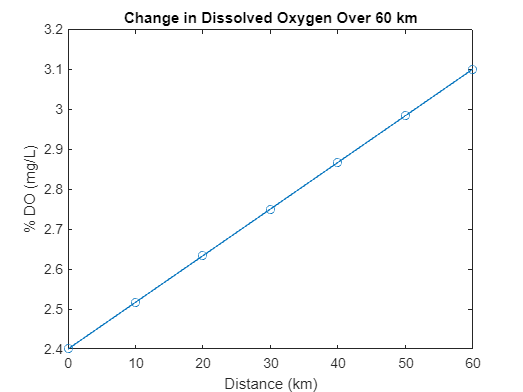


Dist = [0, 10, 20, 30, 40, 50, 60]; %distance in km

DO = 5*((48+(DOsat*Dist))/100); %DO in mg/L


figure
plot(Dist,DO,'o-')
title(["Change in Dissolved Oxygen Over 60 km"])
ylabel("% DO (mg/L)")
xlabel("Distance (km)")

**Discussion:**

- Dissolved oxygen increases over distance, which makes sense in this case because the atlitude is decreasing with increasing distance. This means that the amount of oxygen should increase.

**16.)**

**Given:**

- Initial DO reading = $1\;\mathrm{mg}/L$

- Temperature = $20\degree C$

- Rearation rate = $0\ldotp 8/\mathrm{day}$

- Second DO reading = $5\ldotp 6\;\mathrm{mg}/L$

- Third DO reading = $3\ldotp 6\;\mathrm{mg}/L$

C1 = 1;
C2 = 5.6;
C3 = 3.6;
C4 = 7;
k = 0.8; %reaeration rate

**Required:**

Calculate how long it will take for the DO to reach $7\;\mathrm{mg}/L$ starting from the initial DO reading of $1\;\mathrm{mg}/L$.

**Sketch:**

**Theory:**

This problem will be solved using the first-order kinetics equation rearranged to solve for time (days) for both the first and second rearation.


$$C=C_0 +\left(k*C_0 *T\right)\longrightarrow T=\frac{C-C_0 }{k*C_0 }$$


**Assumptions:**

- Assuming first-order kinetics because of the units of the reaeration rate (${\mathrm{time}}^{-1}$).

**Solution:**

- First aeration:

T1 = (C2-C1)/(k*C1) %time in days

T1 = 5.7500

- Second aeration:

T2 = (C4-C3)/(k*C3) %time in days

T2 = 1.1806

- Final time required = $T_1 +T_2 =5\ldotp 75\;\mathrm{days}+1\ldotp 18\;\mathrm{days}=6\ldotp 93\;\mathrm{days}$

**Discussion:**

- It will take just under seven days for the dissolved oxygen concentration to reach $7\;\mathrm{mg}/L$ using the given parameters.

**17.)**

**Given:**

- Reaeration rate at $30\degree C$ = $0\ldotp 5/\mathrm{day}$

**Required:**

- Plot the DO concentration profile in mg/L from $t^* =0$ to $t^* =5$ days.

**Sketch:**

**Theory:**

- I will use first-order kinetics to solve this problem with following equation:


$$C=C_0 +\left(k*C_0 *T\right)$$


- I will also calculate the rearation rate (k) at $t^* =0$ ($20\degree C$) using the following equation and assuming that the process dependent constant ($\theta$) = 1.075:


$$k\left(20\right)=k\left(30\right)*\theta^{20-30}$$


k30 = 0.5; %1/day
k20 = k30*(1.075^(20-30)) %1/day

k20 = 0.2426

**Assumptions:**

- Assume first-order kinetics

- Assume temperature is $20\degree C$ at $t^* =0$, then immediately increasing to $30\degree C$.

- Assume initial DO of $10\;\mathrm{mg}/L$

**Solution:**

- I calculated the initial concentration at  $t^* =0$ using a rearation rate of 0.2426/day:

C0 = 10 + (k20*10)%mg/L

C0 = 12.4260

- I then calculated and plotted the rest of the DO concentration profile up to $t^* =5\;\mathrm{days}$ using k = 0.5/days and a starting DO concentration of 12.43 mg/L:

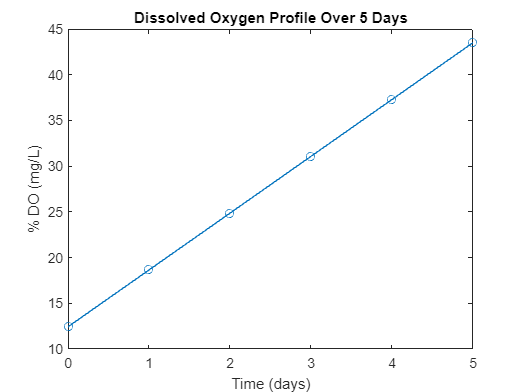

T = [0, 1, 2, 3, 4, 5]; %days
C = 12.43 + (k30*12.43*T); %mg/L

figure
plot(T,C,'o-')
title(["Dissolved Oxygen Profile Over 5 Days"])
ylabel("% DO (mg/L)")
xlabel("Time (days)")

**Discussion:**

- The dissolved oxygen profile shows a linear increase in concentration from a starting value of 12.43 mg/L up to a final value of 43.5 mg/L at $30\degree C$.